# 离散型一维系统MPC控制

## 系统定义 - 参照《控制之美卷2》P58

定义如下的简单一维模型

x[k+1] = x[k] + u[k]

系统的初始条件是：x[0] = 1

系统的控制目标是：xd = 0

clear
close all
clc

% 系统定义
A = 1;
B = 1;
% 系统状态维度计算
n = size (A,1);
p = size (B,2);
% 状态代价权重系数
Q = 1;
% 终值代价权重系数
S = 1;
% 系统输入代价权重系数
R = 1;

## 定义MPC控制器参数

% 定义预测区间
% 注意：预测区间要小于系统运行步数
% Predict horizon
N_P = 5; 
% 定义系统运行步数
k_steps = 5;
% 初始化系统状态矩阵 - 在线
x_history = zeros(n,k_steps);
% 初始化系统输入矩阵 - 在线
u_history = zeros(p,k_steps);
% 初始化MPC计算得到的输入控制序列矩阵
U_history = zeros(k_steps,N_P);

% 根据初始条件，对系统状态进行初始化
x_0 = 1;
% 系统初始状态赋值 - 在线
x = x_0;
% 系统初始状态存入状态矩阵的第一个位置 - 在线
x_history (:,1) = x;



在本例中，预测区间与控制区间相等

## 将MPC问题通过【大大大矩阵】转化为QP问题

% 调用模块[F4]计算二次规划需用到的矩阵
% 实际意义是将MPC问题转化成了QP问题
[Phi,Gamma,Omega,Psi,F,H] = F4_MPC_Matrices_PM(A,B,Q,R,S,N_P);

## 求解QP问题

所谓预测：

通过不断地最小化目标函数J（可以由控制序列U矩阵、F矩阵、H矩阵以及x表示），

求解出每一个系统运行步长时所求解出来的最优控制序列，

对于每一个系统运行步长，只取控制序列的第一项。

for k = 1 : k_steps
    % 调用模块[F5]利用二次规划计算无约束系统的控制 - 在线
    [U,u] = F5_MPC_Controller_noConstraints(x,F,H,p);
    % 计算系统响应 - 在线
    % 也即所谓意义上的"预测"
    x = A * x + B * u ;
    % 将系统状态以及输入保存进相应的矩阵
    % 保存系统状态 - 在线 
    x_history (:,k+1) =  x;
    % 保存MPC控制器每一步输出的控制序列
    U_history (k,:)= U';
    % 保存系统输入 - 在线
    u_history (:,k) = u;
end


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>

找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在

% 观察MPC控制器每一步输出的控制序列
% 每一行为一个控制序列
U_history

U_history =    -0.6180   -0.2360   -0.0899   -0.0337   -0.0112
   -0.2361   -0.0901   -0.0343   -0.0129   -0.0043
   -0.0902   -0.0344   -0.0131   -0.0049   -0.0016
   -0.0345   -0.0132   -0.0050   -0.0019   -0.0006
   -0.0132   -0.0050   -0.0019   -0.0007   -0.0002


% 观察最优控制序列
% 事实上，也就是上面的控制序列的每一行的第一个元素
u_history

u_history =    -0.6180   -0.2361   -0.0902   -0.0345   -0.0132


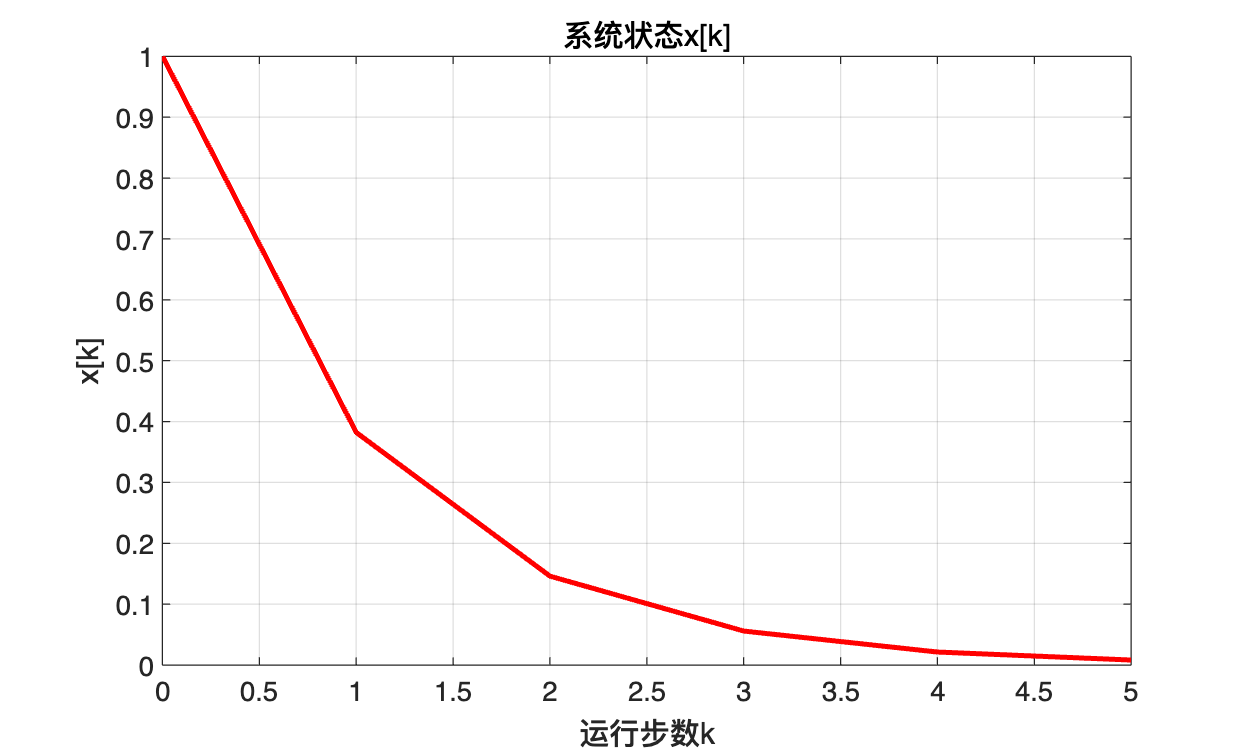

% 系统状态结果视图
figure(1)
% 设置图窗的大小尺寸（单位是像素）
set(gcf, 'Position', [100, 100, 500, 300]) % [left, bottom, width, height]
plot (0:length(x_history)-1, x_history(1,:),'r','LineWidth',2);
grid on
title("系统状态x[k]")
xlabel("运行步数k")
ylabel("x[k]")

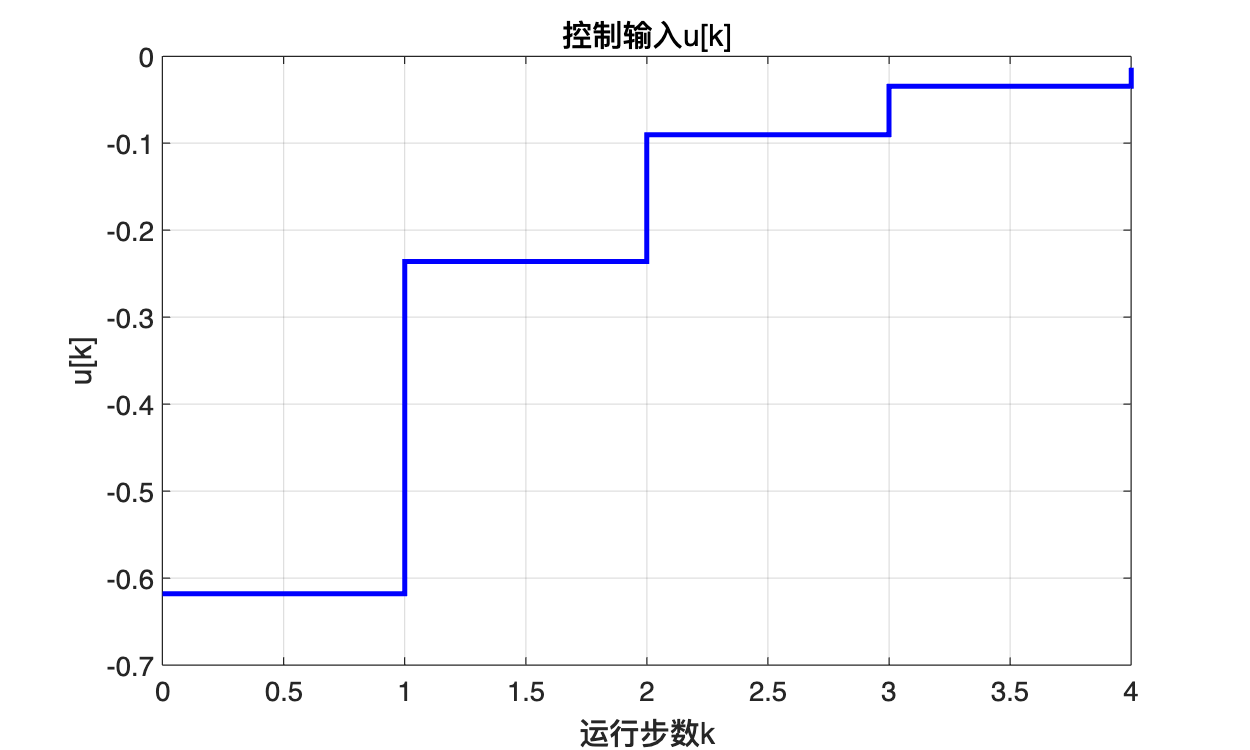

% 系统输入结果视图 
figure(2)
set(gcf, 'Position', [100, 100, 500, 300]) % [left, bottom, width, height]
stairs (0:length(u_history)-1,u_history(1,:),'b','LineWidth',2);
title("控制输入u[k]")
xlabel("运行步数k")
ylabel("u[k]")
grid on

# 离线MPC

所谓“离线”，即直接采用由初始状态计算得到的控制区间的控制序列来控制系统，

而不是每次只采用控制序列的第一个，

然后在每一步都更新一遍控制序列。

这样做，其实只计算了一次控制序列，并认为这个控制序列中的控制量输入都是现有情况下“最优”的。

% 系统初始状态赋值 - 离线
x_offline = x_0;
% 初始化系统状态矩阵 - 离线
x_history_offline = zeros(n,k_steps);
% 初始化系统输入矩阵 - 离线
u_history_offline = zeros(p,k_steps);
% 系统初始状态存入状态矩阵的第一个位置 - 离线
x_history_offline (:,1) = x_0;
% 初始化MPC计算得到的输入控制序列矩阵 - 离线
U_history_offline = zeros(k_steps,N_P);

% 调用模块[F5]利用二次规划计算无约束系统的控制 - 离线
[U_offline, u_offline]= F5_MPC_Controller_noConstraints(x_offline,F,H,p)


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


U_offline =    -0.6180
   -0.2360
   -0.0899
   -0.0337
   -0.0112


u_offline = -0.6180

% 这个循环意义其实不是循环求解最优控制序列
% 而是将预先离线计算好的控制序列，在每一个控制步长输入给系统后，记录系统状态
for k = 1 : k_steps
    % 系统输入赋值 - 离线
    u_offline = U_offline(k);
    % 计算系统给响应 - 离线
    x_offline = A * x_offline + B * u_offline 
    % 保存系统状态 - 离线
    x_history_offline (:,k+1) =  x_offline;
    % 保存系统输入 - 离线
    U_history_offline (:,k) =  u_offline;
    
end

x_offline = 0.3820

x_offline = 0.1461

x_offline = 0.0562

x_offline = 0.0225

x_offline = 0.0112

U_history_offline

U_history_offline =    -0.6180   -0.2360   -0.0899   -0.0337   -0.0112
   -0.6180   -0.2360   -0.0899   -0.0337   -0.0112
   -0.6180   -0.2360   -0.0899   -0.0337   -0.0112
   -0.6180   -0.2360   -0.0899   -0.0337   -0.0112
   -0.6180   -0.2360   -0.0899   -0.0337   -0.0112


## 绘图对比离线MPC与在线MPC

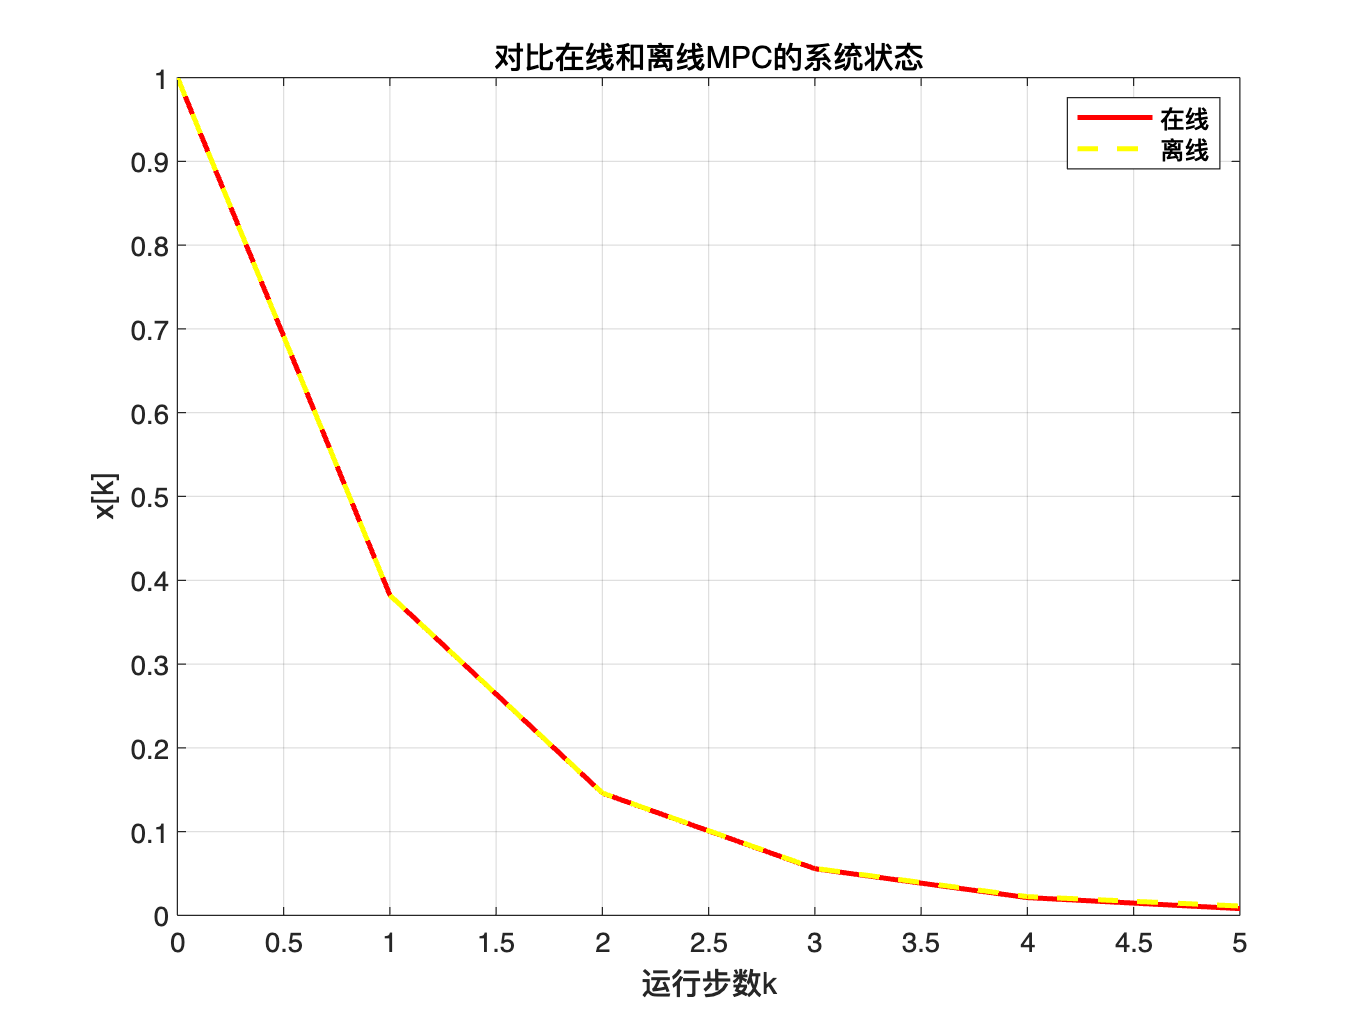

figure(3)
plot (0:length(x_history)-1,x_history(1,:),'r','LineWidth',2);
hold on
plot (0:length(x_history_offline)-1,x_history_offline(1,:),'y--','LineWidth',2);
grid on
legend("在线","离线")
title("对比在线和离线MPC的系统状态")
xlabel("运行步数k")
ylabel("x[k]")
hold off

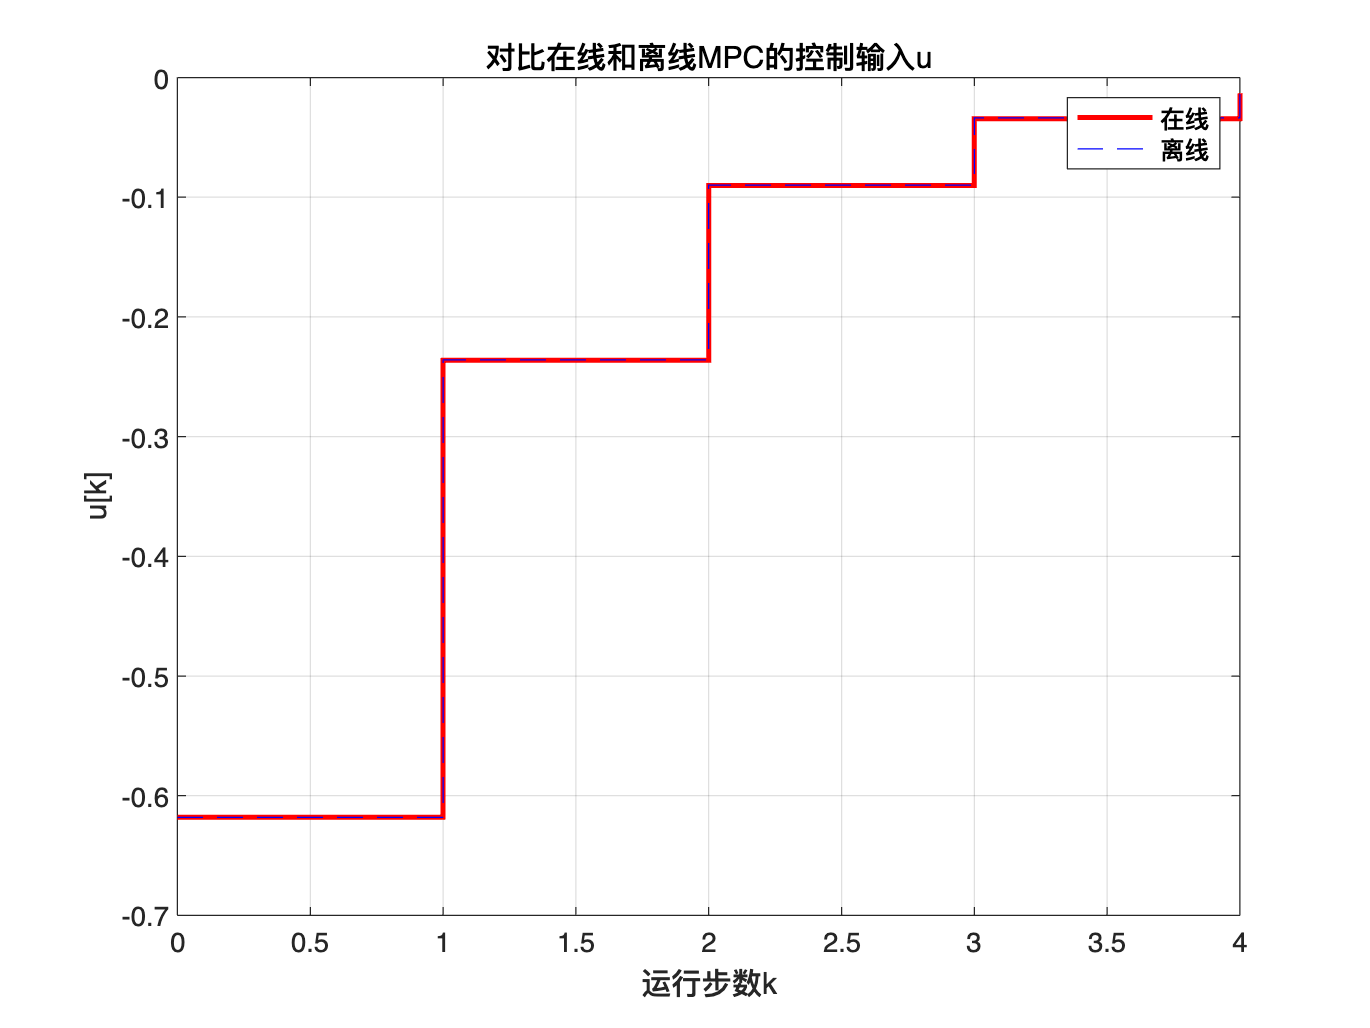

figure(4)
stairs (0:length(u_history)-1,u_history(1,:),'r','LineWidth',2);
hold on
stairs (0:length(U_history_offline(1,:))-1,U_history_offline(1,:),'b--');
grid on
legend("在线","离线")
title("对比在线和离线MPC的控制输入u")
xlabel("运行步数k")
ylabel("u[k]")
hold off

可以看到，在理想情况（系统无任何扰动时），离线计算的控制序列就已经比较理想了，与在线MPC的控制效果差不多。

但是，一旦系统运行中出现任何扰动，离线MPC计算的控制序列就不再是最优解，也会导致控制效果很差。

具体参见书P108图5.3.3